# Talleres 13 y 14. Modelo de un péndulo simple

## Descripción del sistema

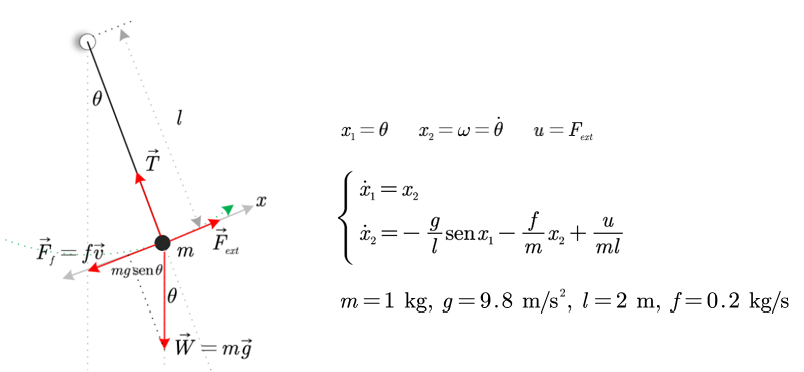

## 1. Simulación temporal

Observar que el valor máximo de la fuerza es de 7.5 N, menor que mg = 9.8 N. El valor es menor debido a que una baja fricción hará que el sobreimpulso sea grande y el sistema adquiera una velocidad que haga que no se estabilice.

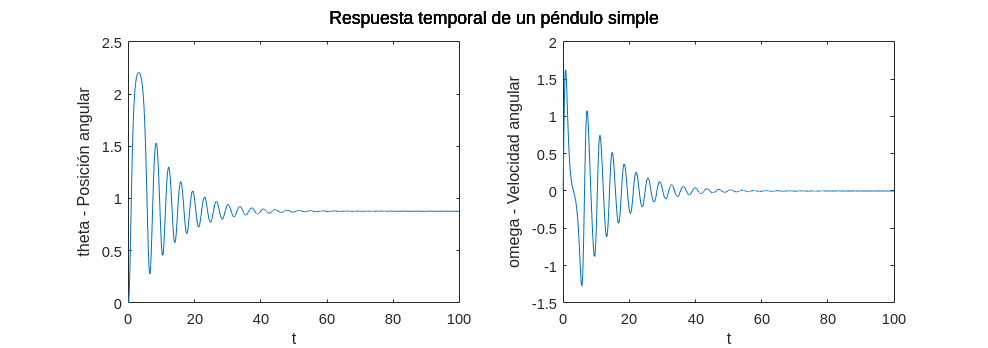

syms x1(t) x2(t)
m = 1; g = 9.8; l = 2; f = 0.2;
u = 7.5; % umax = 7.55
f1 = x2;
f2 = -(g/l)*sin(x1) -(f/m)*x2 + u/(m*l);
fun = odeFunction([f1 f2],[x1 x2]); 
tspan = 0:0.01:100;
ci = [0 0];
[t,sol] = ode45(fun,tspan,ci); 
theta = sol(:,1); omega = sol(:,2);
h1 = figure;
subplot(1,2,1), plot(t,theta), xlabel('t'), ylabel('theta - Posición angular')
subplot(1,2,2), plot(t,omega), xlabel('t'), ylabel('omega - Velocidad angular')
set(h1,'Units','normalized','Position',[0 0 0.8 0.5]);
sgtitle('Respuesta temporal de un péndulo simple')

## 2. Curva de linealidad

Observar la curva de linealidad, la cual no corresponde a una recta. Mostrar la relación con los puntos de equilibrio (cada círculo en el gráfico es un punto de equilibrio).

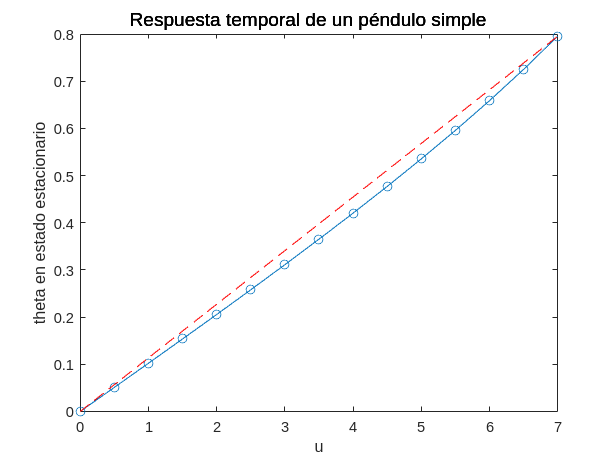

syms x1(t) x2(t)
m = 1; g = 9.8; l = 2; f = 0.2;
f1 = x2;
uspan = 0:0.5:7;
N = length(uspan);
theta = zeros(1,N);
tspan = 0:0.1:100;
ci = [0 0];
for i=1:N
    u = uspan(i);
    f2 = -(g/l)*sin(x1) -(f/m)*x2 + u/(m*l); 
    fun = odeFunction([f1 f2],[x1 x2]); 
    [~,sol] = ode45(fun,tspan,ci);
    theta(i) = sol(end,1);
end
h2 = figure;
plot(uspan,theta,'o-',[0 uspan(end)],[0 theta(end)],'r--'), xlabel('u'), ylabel('theta en estado estacionario')

## 3. Retrato de fase (espacio de fase) con cambio de omega(0)

Observar el número de vueltas que da el péndulo a partir de omega(0) = 4. Poner atención a los puntos de equilibrio.

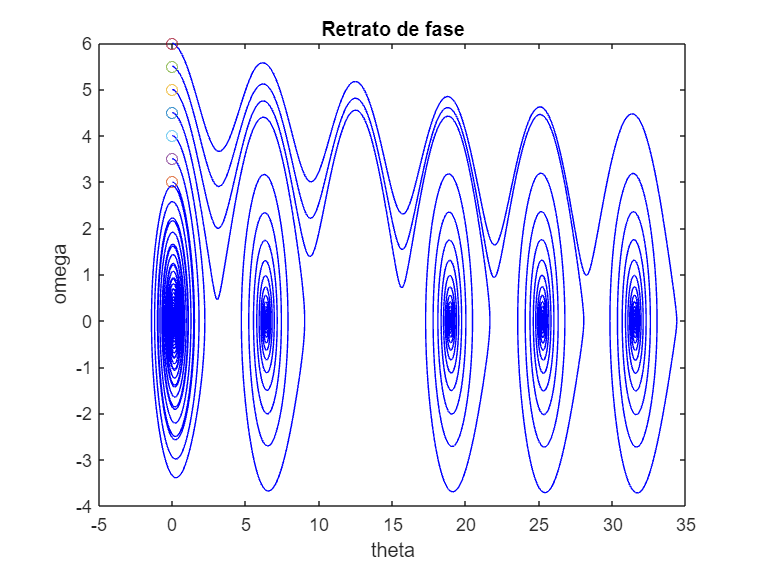

syms x1(t) x2(t)
m = 1; g = 9.8; l = 2; f = 0.2;
u = 1;
f1 = x2;
f2 = -(g/l)*sin(x1) -(f/m)*x2 + u/(m*l);
fun = odeFunction([f1 f2],[x1 x2]);
tspan = 0:0.01:100;
omega0 = 3:0.5:6;
figure
for i=1:length(omega0)
    ci = [0 omega0(i)]; 
    [~,sol] = ode45(fun,tspan,ci);
    theta = sol(:,1); omega = sol(:,2);
    plot(theta,omega,'b',ci(1),ci(2),'o'), xlabel('theta'), ylabel('omega'), title('Retrato de fase')
    hold on
end

## 4. Retrato de fase (espacio de fase) con cambio de theta(0)

Observar el número de vueltas que da el péndulo a partir de omega(0) = 4. Poner atención a los tres puntos de equilibrio y que no puede haber más.

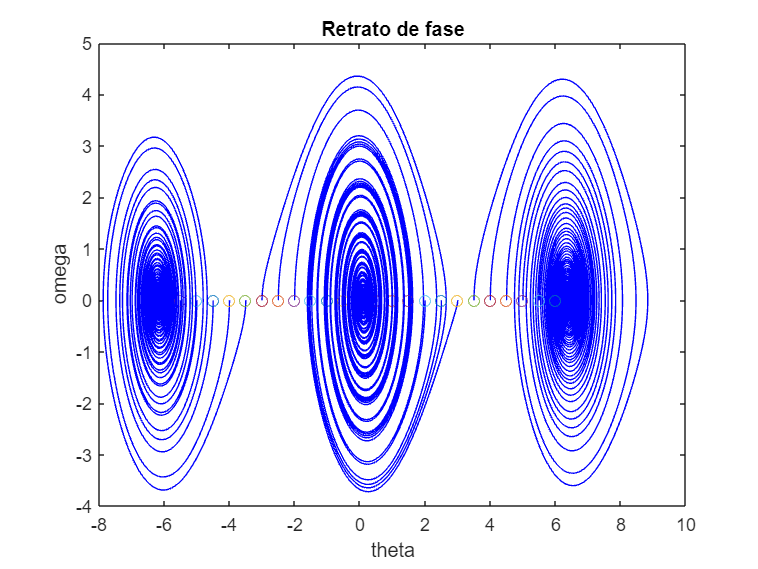

syms x1(t) x2(t)
m = 1; g = 9.8; l = 2; f = 0.2;
u = 1;
f1 = x2;
f2 = -(g/l)*sin(x1) -(f/m)*x2 + u/(m*l);
fun = odeFunction([f1 f2],[x1 x2]);
tspan = 0:0.01:100;
theta0 = -6:0.5:6;
figure
for i=1:length(theta0)
    ci = [theta0(i) 0]; 
    [~,sol] = ode45(fun,tspan,ci);
    theta = sol(:,1); omega = sol(:,2);
    plot(theta,omega,'b',ci(1),ci(2),'o'), xlabel('theta'), ylabel('omega'), title('Retrato de fase')
    hold on
end

## 5. Cambio de la longitud del péndulo

Observar el efecto en la amplitud máxima, tiempo del primer pico y el cuasiperíodo. No hay efecto mayor en el tiempo de estabilización.

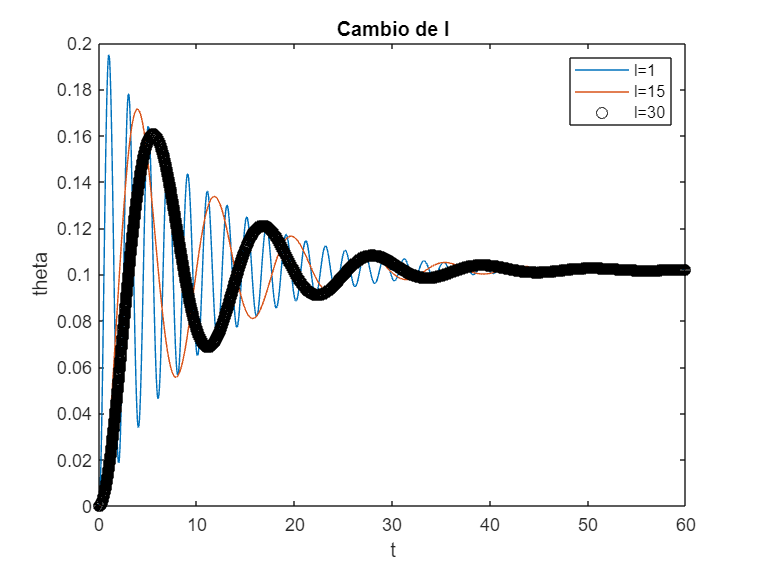

syms x1(t) x2(t)
m = 1; g = 9.8; f = 0.2;
u = 1;
f1 = x2;
ci = [0 0];
tspan = 0:0.01:60;
figure
l = 1; f2 = -(g/l)*sin(x1) -(f/m)*x2 + u/(m*l); fun = odeFunction([f1 f2],[x1 x2]); [t,sol] = ode45(fun,tspan,ci); theta1 = sol(:,1);
l = 15; f2 = -(g/l)*sin(x1) -(f/m)*x2 + u/(m*l); fun = odeFunction([f1 f2],[x1 x2]); [~,sol] = ode45(fun,tspan,ci); theta2 = sol(:,1);
l = 30; f2 = -(g/l)*sin(x1) -(f/m)*x2 + u/(m*l); fun = odeFunction([f1 f2],[x1 x2]); [~,sol] = ode45(fun,tspan,ci); theta3 = sol(:,1);
plot(t,theta1,t,theta2,t,theta3,'ko'), xlabel('t'), ylabel('theta'), title('Cambio de l'), legend({'l=1','l=15','l=30'})

## 6. Cambio de la masa del péndulo

Observar el efecto en la amplitud máxima, tiempo de estabilización y valor de estabilización. No afecta el cuasiperíodo. Observar que la masa está en el denominador de la ecuación y por eso la inercia tiene un efecto inverso en la amplitud de las oscilaciones. La masa afecta el peso y hace que se estabilice en un ángulo más pequeño.

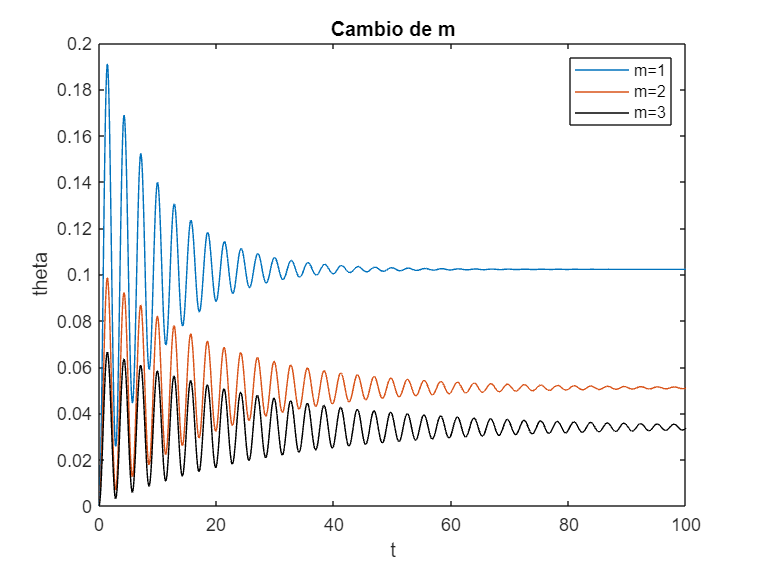

syms x1(t) x2(t)
l = 2; g = 9.8; f = 0.2;
u = 1;
f1 = x2;
ci = [0 0];
tspan = 0:0.1:100;
figure
m = 1; f2 = -(g/l)*sin(x1) -(f/m)*x2 + u/(m*l); fun = odeFunction([f1 f2],[x1 x2]); [t,sol] = ode45(fun,tspan,ci); theta1 = sol(:,1);
m = 2; f2 = -(g/l)*sin(x1) -(f/m)*x2 + u/(m*l); fun = odeFunction([f1 f2],[x1 x2]); [~,sol] = ode45(fun,tspan,ci); theta2 = sol(:,1);
m = 3; f2 = -(g/l)*sin(x1) -(f/m)*x2 + u/(m*l); fun = odeFunction([f1 f2],[x1 x2]); [~,sol] = ode45(fun,tspan,ci); theta3 = sol(:,1);
plot(t,theta1,t,theta2,t,theta3,'k'), xlabel('t'), ylabel('theta'), title('Cambio de m'), legend({'m=1','m=2','m=3'})

## 7. Cambio de la fricción del péndulo

Observar el efecto en la amplitud máxima y tiempo de estabilización. No afecta el cuasiperíodo ni el valor de estabilización. Observar que la masa está en el denominador de la ecuación y por eso la inercia tiene un efecto inverso en la amplitud de las oscilaciones. La masa afecta el peso y hace que se estabilice en un ángulo más pequeño.

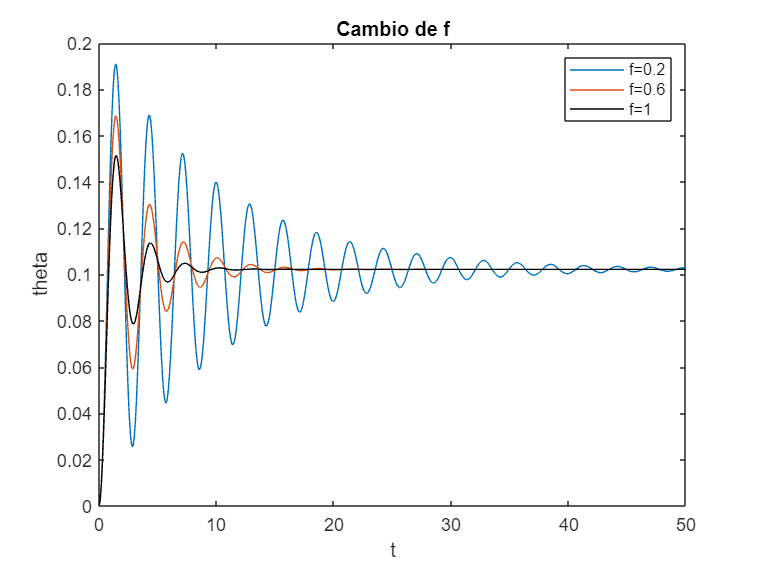

syms x1(t) x2(t)
m = 1; l = 2; g = 9.8; 
u = 1;
f1 = x2;
ci = [0 0];
tspan = 0:0.1:50;
figure
f = 0.2; f2 = -(g/l)*sin(x1) -(f/m)*x2 + u/(m*l); fun = odeFunction([f1 f2],[x1 x2]); [t,sol] = ode45(fun,tspan,ci); theta1 = sol(:,1);
f = 0.6; f2 = -(g/l)*sin(x1) -(f/m)*x2 + u/(m*l); fun = odeFunction([f1 f2],[x1 x2]); [~,sol] = ode45(fun,tspan,ci); theta2 = sol(:,1);
f = 1; f2 = -(g/l)*sin(x1) -(f/m)*x2 + u/(m*l); fun = odeFunction([f1 f2],[x1 x2]); [~,sol] = ode45(fun,tspan,ci); theta3 = sol(:,1);
plot(t,theta1,t,theta2,t,theta3,'k'), xlabel('t'), ylabel('theta'), title('Cambio de f'), legend({'f=0.2','f=0.6','f=1'})

## 8. Movimiento libre no amortiguado

La ecuación diferencial es θ'' + (g/l)θ = 0. La solución es: θ = Asin(ωt + φ), con $\omega =\sqrt{\frac{g}{l}}$ y $P=2\pi \sqrt{\frac{l}{g}}$. La expresión se comprueba si θ(0) = 0.5, pero no si θ(0) = 1.5.

syms x1(t) x2(t)
m = 1; l = 2; f = 0; g = 9.8; 
u = 0;
f1 = x2;
f2 = -(g/l)*sin(x1) -(f/m)*x2 + u/(m*l); 
fun = odeFunction([f1 f2],[x1 x2]);
ci = [0.5 0];
tspan = 0:0.1:10;
[t,sol] = ode45(fun,tspan,ci); 
theta = sol(:,1);
P = 2*pi*sqrt(l/g); % Período que coincide aproximadamente con el del gráfico: P = 5.8 - 2.9 = 2.9
disp(P)

    2.8385


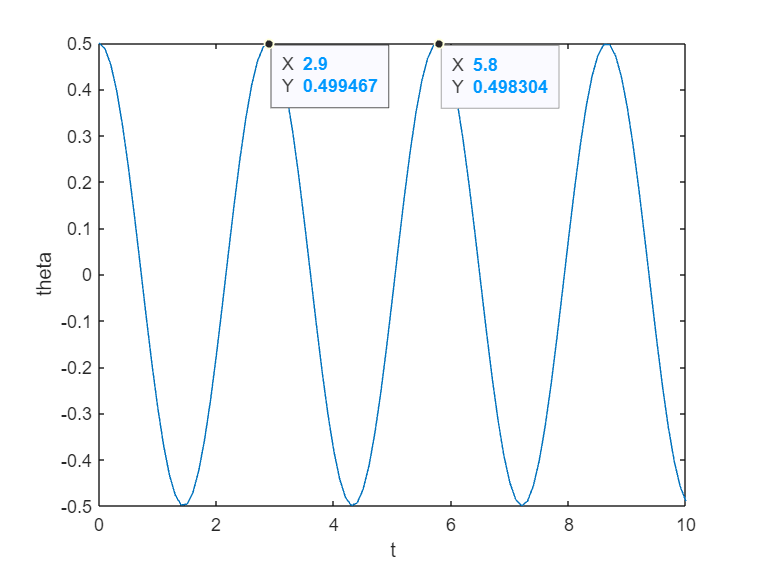

figure
plot(t,theta), xlabel('t'), ylabel('theta')
ax2 = gca; chart2 = ax2.Children(1); datatip(chart2,5.8,0.4983); datatip(chart2,2.9,0.4995);

ci = [1.5 0];
tspan = 0:0.1:10;
[t,sol] = ode45(fun,tspan,ci); 
theta = sol(:,1);
P = 2*pi*sqrt(l/g); % Período que no coincide aproximadamente con el del gráfico: P = 6.6 - 3.3 = 3.3
disp(P)

    2.8385


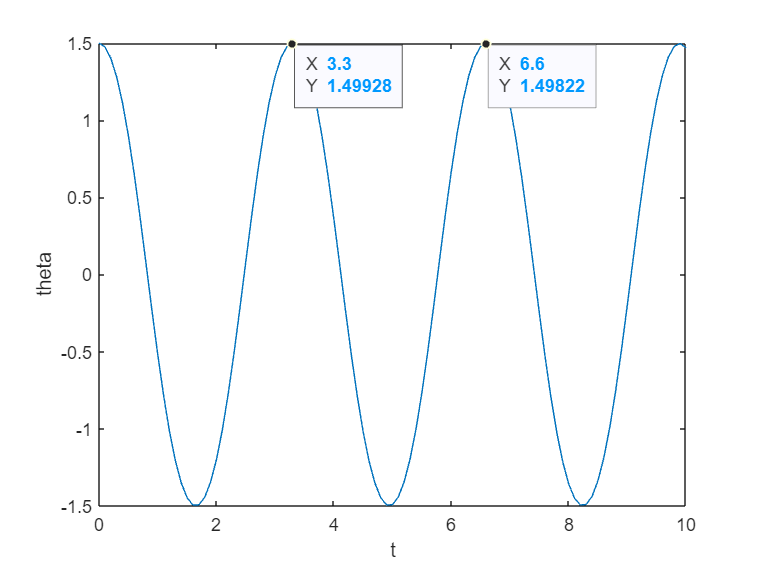

figure
plot(t,theta), xlabel('t'), ylabel('theta')
ax = gca; chart = ax.Children(1); datatip(chart,6.6,1.498); datatip(chart,3.3,1.499);

## 9. Cálculo experimental de f y m

Observar el efecto de la masa (tarea 6) y de la fricción (tarea 7) sobre la respuesta temporal. Es decir, para subir el valor final se debe disminuir la masa y para disminuir la amplitud se debe subir la fricción. (*) Los valores exactos son f = 0.61 y m = 0.52.

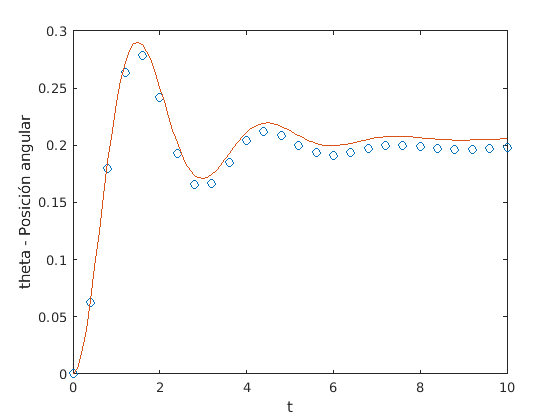

t_exp = 0:0.4:10;
theta_exp = [0 0.0621 0.1797 0.2635 0.2783 0.2414 0.1932 0.1656 0.1667 0.1852 0.2038 0.2119 0.2086 0.2002 0.1934 0.1915 0.1938 0.1973 0.1997 0.1999 0.1987 0.1972 0.1965 0.1966 0.1972 0.1978];
syms x1(t) x2(t)
m = 1; f = 0.2;
g = 9.8; l = 2; 
u = 1;
f1 = x2;
f2 = -(g/l)*sin(x1) -(f/m)*x2 + u/(m*l);
fun = odeFunction([f1 f2],[x1 x2]);
tspan = 0:0.1:10;
ci = [0 0];
[t,sol] = ode45(fun,tspan,ci); 
theta = sol(:,1); 
figure;
plot(t_exp,theta_exp,'o',t,theta), xlabel('t'), ylabel('theta - Posición angular')